# Final Project - Applied Machine Learning

## Victor A. da Silva - MECH580

# Introduction

In molecular and cellular biology, it is widely known that the composition of cells determines their structure, which in turn determines their function. Therefore, cells with different morphologies are likely to have different functions. In this context, the distinction between stem cells and trophoblasts is of great interest. Trophoblasts are cells that make up the outer layer of a developing human embryo, and they have a unique shape that distinguishes them from other cells.

Stem cells and trophoblasts have distinct morphologies and functions. Stem cells are characterized by their ability to differentiate into various cell types and can be found in both embryonic and adult tissues. On the other hand, trophoblasts play a crucial role in the implantation of the embryo and the development of the placenta. Trophoblasts also have a unique ability to invade the maternal uterus, which is essential for successful pregnancy.

To distinguish between stem cells and trophoblasts, various approaches have been used, including protein and genetic expression analysis. However, these methods have their limitations, such as being time-consuming and expensive, requiring a large number of cells, and having low sensitivity and specificity.

Recently, with the advent of deep learning techniques, there has been a growing interest in using convolutional neural networks (CNNs) to classify cells based on their morphology. A CNN can learn to extract features from images and use these features to distinguish between different cell types. Using a CNN to classify cells would be time and money-saving, as it requires only a small number of cells, and the analysis can be performed quickly and accurately using a microscope. In this study, we aimed to develop a CNN model to distinguish between stem cells and trophoblasts based on their morphologies.

## Implementation of Liu et al., 2021

Based on the mentioned importance of cell morphology and composition, distinguishing between different cell types can provide valuable information for various applications in molecular and cellular biology. In this project, I selected an article that implemented pre-trained neural networks, including DenseNet, VGG16, VGG19, InceptionV3, and Xception, to distinguish between two types of cells: trophoblasts and embryonic stem (ES) cells. The article trained these models using 1500 images and Python language. As part of my project, I adapted their work to Matlab and tested the trained models using my own images, which I collected in my laboratory.

# Methods

The dataset used in this project was provided by Liu and his collaborators and is available for download at the following link: [https://zenodo.org/record/4181358](https://zenodo.org/record/4181358). This dataset includes 1500 images of stem cells and trophoblasts, which were used to train and test the pre-trained neural networks implemented in this project. 

## Imaging processing

In order to use our dataset in the pre-trained Neural Networks, we will need to resize our images, first let's check their original size:

% Load an example image
img = imread('C:\Users\victo\Downloads\Machine Learning Course\Project\dataset_sample\ES\ES_000.tif');

% Get the size of the image array
img_size = size(img)

img_size =         2000        2000           3


Since we have a lot of images to resize, we can use a very useful tool from Matlab:

**Image Batch Processor** - a tool from Matlab

To process our images, I will create two batches of images: 

1. Images of 224 x 224 x 3 to DenseNet, VGG16 and VGG19;

% Load an example image
img = imread('C:\Users\victo\Downloads\Machine Learning Course\Project\dataset_batch1\ES\ES_000_output.tif');

% Get the size of the image array
img_size = size(img)

img_size =    224   224     3


2. Images of 299 x 299 x 3 to InceptionV3 and Xception;

% Load an example image
img = imread('C:\Users\victo\Downloads\Machine Learning Course\Project\dataset_batch2\ES\ES_000_output.tif');

% Get the size of the image array
img_size = size(img)

img_size =    299   299     3


 More informations can be find in the code: image_proc_batch1.m and image_proc_batch2.m

clc
clear all
close all
fpath = 'C:\Users\victo\Downloads\Machine Learning Course\Project';

% Let's import our data collections
data_batch1 = fullfile(fpath,'dataset_batch1');
data_batch2 = fullfile(fpath,'dataset_batch2');

### Creating a Data Store

Firs of all let's create a Data Store with the images that we have, it is important to mention that we need each set of images organized into different folders

tdata1=imageDatastore(data_batch1,'includesubfolders',true,'LabelSource','foldernames');
count1=tdata1.countEachLabel

count1 = 2×2 table
    Label    Count
    _____    _____

     ES       108 
     T        108 



tdata2=imageDatastore(data_batch2,'includesubfolders',true,'LabelSource','foldernames');
count2=tdata2.countEachLabel

count2 = 2×2 table
    Label    Count
    _____    _____

     ES       108 
     T        108 


Let's split our training and validation data

[trainingdata1, testdata1] = splitEachLabel(tdata1,0.8,'randomized');
[trainingdata2, testdata2] = splitEachLabel(tdata2,0.8,'randomized');

### Importing pre-trained Neural Networks:

Now let's load the Pre-Trained Network used in reference paper:

(be sure you have all them installed first)

- DenseNet: [`densenet201`](https://www.mathworks.com/help/deeplearning/ref/densenet201.html?searchHighlight=densenet&s_tid=srchtitle_densenet_1#d124e48578)

- VGG16: [`vgg16`](https://www.mathworks.com/help/deeplearning/ref/vgg16.html?s_tid=doc_ta#d124e194654)

- VGG19: [`vgg19`](https://www.mathworks.com/help/deeplearning/ref/vgg19.html?s_tid=doc_ta#d124e195029)

- InceptionV3: [`inceptionv3`](https://www.mathworks.com/help/deeplearning/ref/inceptionv3.html?s_tid=doc_ta#d124e112404)

- Xception:[`xception`](https://www.mathworks.com/help/deeplearning/ref/xception.html?searchHighlight=Xception&s_tid=srchtitle_Xception_1#d124e195901)

net1=densenet201;
net2=vgg16;
net3=vgg19;
net4=inceptionv3;
net5=xception;

### Checking inputs:

Let's double check their input requirements (running the first layer, the input, you can check its specifications):

% net1.Layers(1)
% net2.Layers(1)
% net3.Layers(1)
% net4.Layers(1)
% net5.Layers(1)

The image input for each Neural Network is:

- DenseNet: 224 x 224 x 3

- VGG16: 224 x 224 x 3

- VGG19: 224 x 224 x 3

- InceptionV3: 299 x 299 x 3

- Xception: 299 x 299 x 3

I don't want to change the properties of "imageInputLayer" of these Neural Networks, so instead we are gonna use two different sets of image:

- Batch 1 containing images of 224 x 224 x 3 will be used to DenseNet, VGG16 and VGG19;

- Batch 2 containing Images of 299 x 299 x 3 will be used to InceptionV3 and Xception;

### Adjustments:

As we will be applying transfer learning to pre-trained neural networks, we will need to adjust the FullyConnectedLayer and classificationLayer. This is important because these imported models are specific to their original task for which the network was trained.

The FullyConnectedLayer is typically the final layer before the output of the network, and its size corresponds to the number of classes in the original task. However, since the new task may have a different number of classes, the size of this layer needs to be adjusted accordingly. In our case, it needs to be adjusted for two classes.

The classificationLayer is the final layer of the network that produces the output, and its type is determined by the type of the original task. Since the labels used by these neural networks do not correspond to ours, we will have to create an empty layer and train the model again.

By adjusting the FullyConnectedLayer and classificationLayer, we can fine-tune the pre-trained network to perform well on the new task.

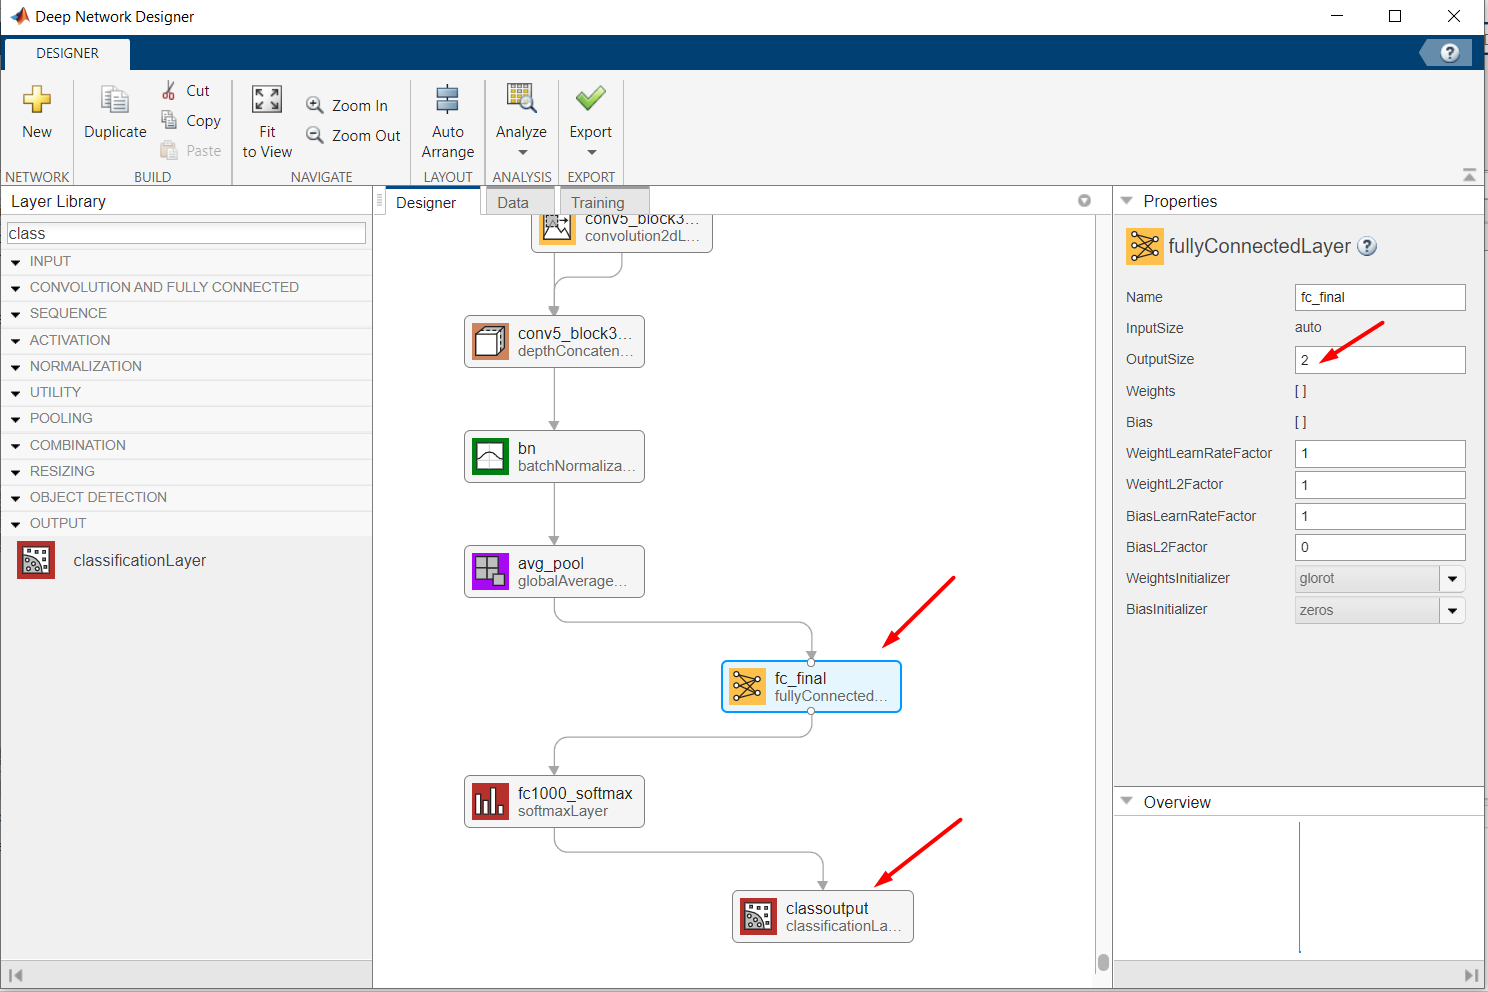

### Options:

In order to make this more comparable, we will use the same training options for all the models. Their settings will be:

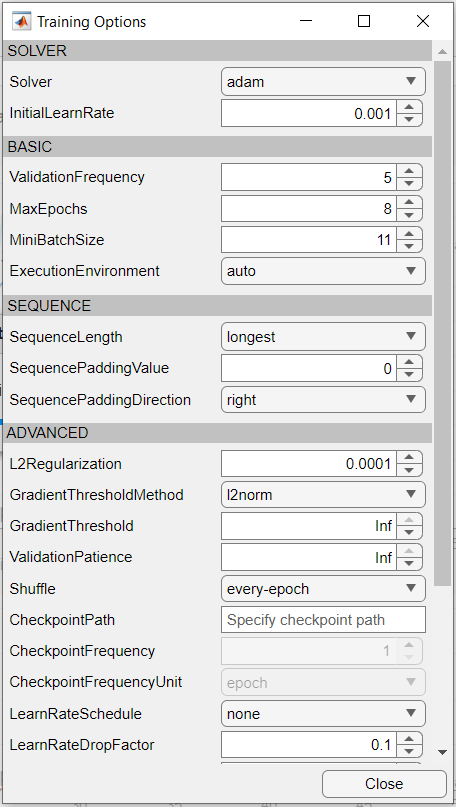

**Adam** (short for Adaptive Moment Estimation) is a popular optimization algorithm for training neural networks, which has several advantages over other optimization algorithms. Here are some advantages of using Adam as a solver for the options during training:

- Fast convergence: Adam has been shown to converge faster than other optimization algorithms, such as stochastic gradient descent (SGD), due to its adaptive learning rate and momentum.

- Adaptive learning rate: Adam adapts the learning rate of each weight parameter based on the gradient of the loss function, which can improve the training efficiency and stability. This is particularly useful for problems where the gradients of the loss function vary widely across different dimensions.

- Robustness to noisy gradients: Adam is robust to noisy or sparse gradients, which can be encountered in problems with large datasets or high-dimensional parameter spaces. This is because Adam maintains a running estimate of the second moment of the gradients, which helps to smooth out the noise.

- Low memory requirements: Adam only requires a small amount of memory to store the first and second moment estimates, which makes it suitable for training large neural networks with limited computational resources.

- No manual tuning of hyperparameters: Adam has only two hyperparameters that need to be set (the learning rate and momentum decay rate), which can be automatically adjusted during training based on the adaptive learning rate and momentum updates.

"**InitialLearnRate**" is a number that controls how fast or slow a neural network learns during training. It's like a step size that determines how much the network's weights and biases are updated at each iteration of the optimization algorithm. A higher "InitialLearnRate" means bigger updates and faster learning, but it can also lead to overshooting and instability. A lower "InitialLearnRate" means smaller updates and slower learning, but it can be more stable and accurate. It's a hyperparameter that needs to be set before training, and can be adjusted during training to fine-tune the model.

The "**ValidationFrequency**" is a setting that determines how often a neural network checks how well it's doing on a validation set of data while it's being trained. During training, the network is typically tested on a separate validation dataset to make sure it's not overfitting (i.e., it's not just memorizing the training set). The "ValidationFrequency" setting determines how often the network checks its performance on the validation dataset, expressed as the number of iterations or batches between each check. Setting a higher value can make training faster but may also result in less frequent monitoring of the network's performance.

The "**MaxEpochs**" parameter is a setting that determines the maximum number of times a neural network will be trained on the entire training dataset during the training process. Each time the network is trained on the entire dataset, it's called an "epoch". Setting a higher "MaxEpochs" value can potentially improve the accuracy of the model, but may also lead to longer training times or overfitting. Setting a lower "MaxEpochs" value can result in faster training times but may lead to underfitting or lower accuracy.

The "**MiniBatchSize**" is a setting that determines the number of training examples that are processed together in each iteration of the training process. Processing examples in batches rather than individually can lead to a more stable estimate of the gradient and can speed up the training process. Setting a higher "MiniBatchSize" value can lead to a more accurate estimate of the gradient but may also lead to higher memory usage and slower training times. Setting a lower "MiniBatchSize" value can result in faster training times but may lead to a noisier estimate of the gradient.

# Training and Testing each model

## DenseNet 

In order to adjust this model for our application, the pre-trained neural network was opened in the Deep Learning Tool and  two layers were adjusted:

% deepNetworkDesigner(net1)

After that the model was trained with the set of images from Batch 1 and here is its performance:

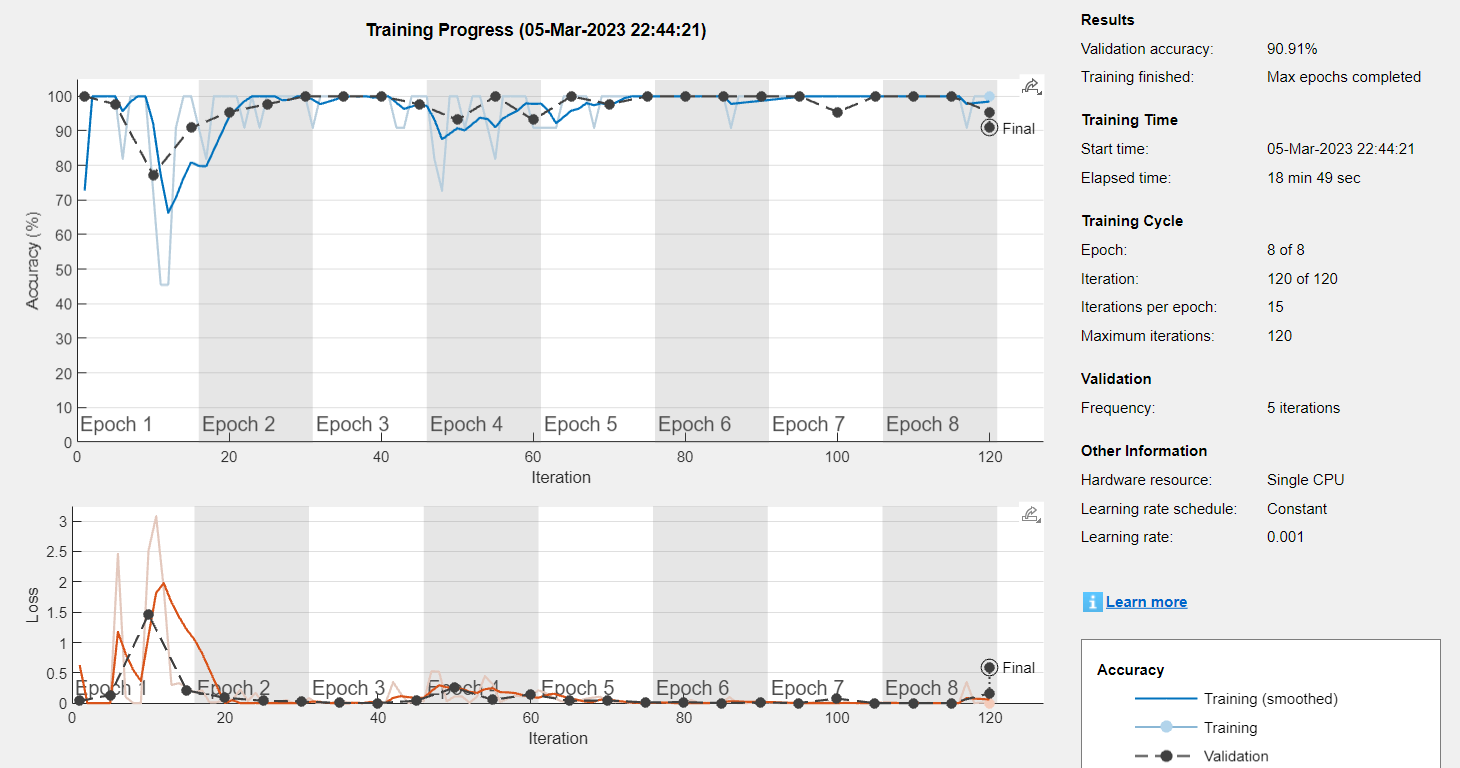

After training and saving our model, we can load it and check its performance to new data:

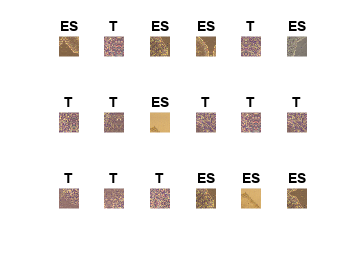

load("DenseNet_trained.mat")

figure(),
allclass=[];
images_analyzed = zeros(1,18);
for i=1:18
    idx = randi(numel(testdata1.Files)); % generate a random index
    images_analyzed(i) = idx;
    I=readimage(testdata1,idx);
    class=classify(DenseNet_trained,I);
    allclass=[allclass class];
    figure(1),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted1=allclass;

Let's generate a confucion matrix

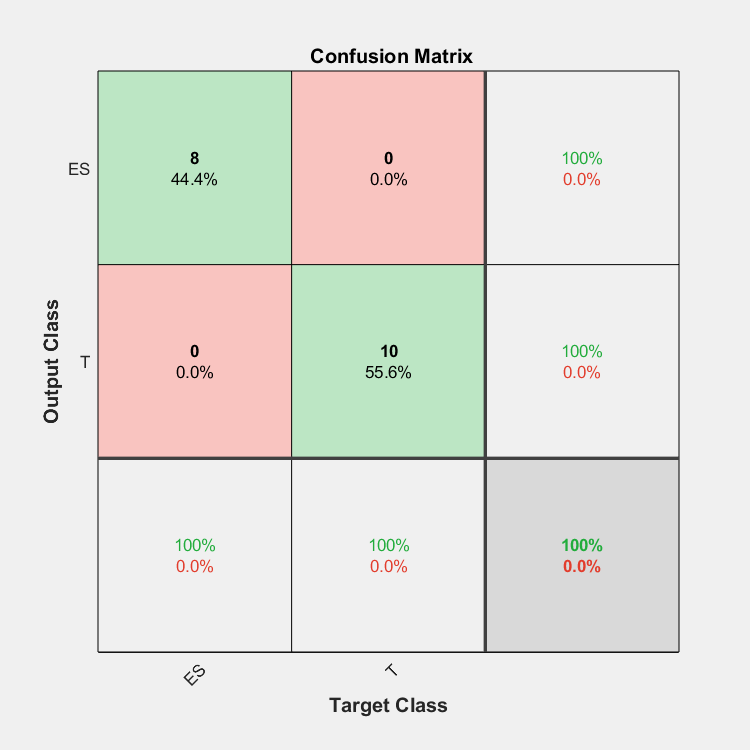

matrix1 =   Figure (PLOTCONFUSION1) with properties:

      Number: 2
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


figure(),
% Do not forget that at least one of the matrix must be transposed to generate a proper answer
matrix1 = plotconfusion(testdata1.Labels(images_analyzed),Predicted1')

Now let's measure its accuracy:

accuracy1 =mean(Predicted1==(testdata1.Labels(images_analyzed))')

accuracy1 = 1

## VGG16

In order to adjust this model for our application, the pre-trained neural network was opened in the Deep Learning Tool and  two layers were adjusted:

% deepNetworkDesigner(net2)

After that the model was trained with the set of images from Batch 1 and here is its performance:

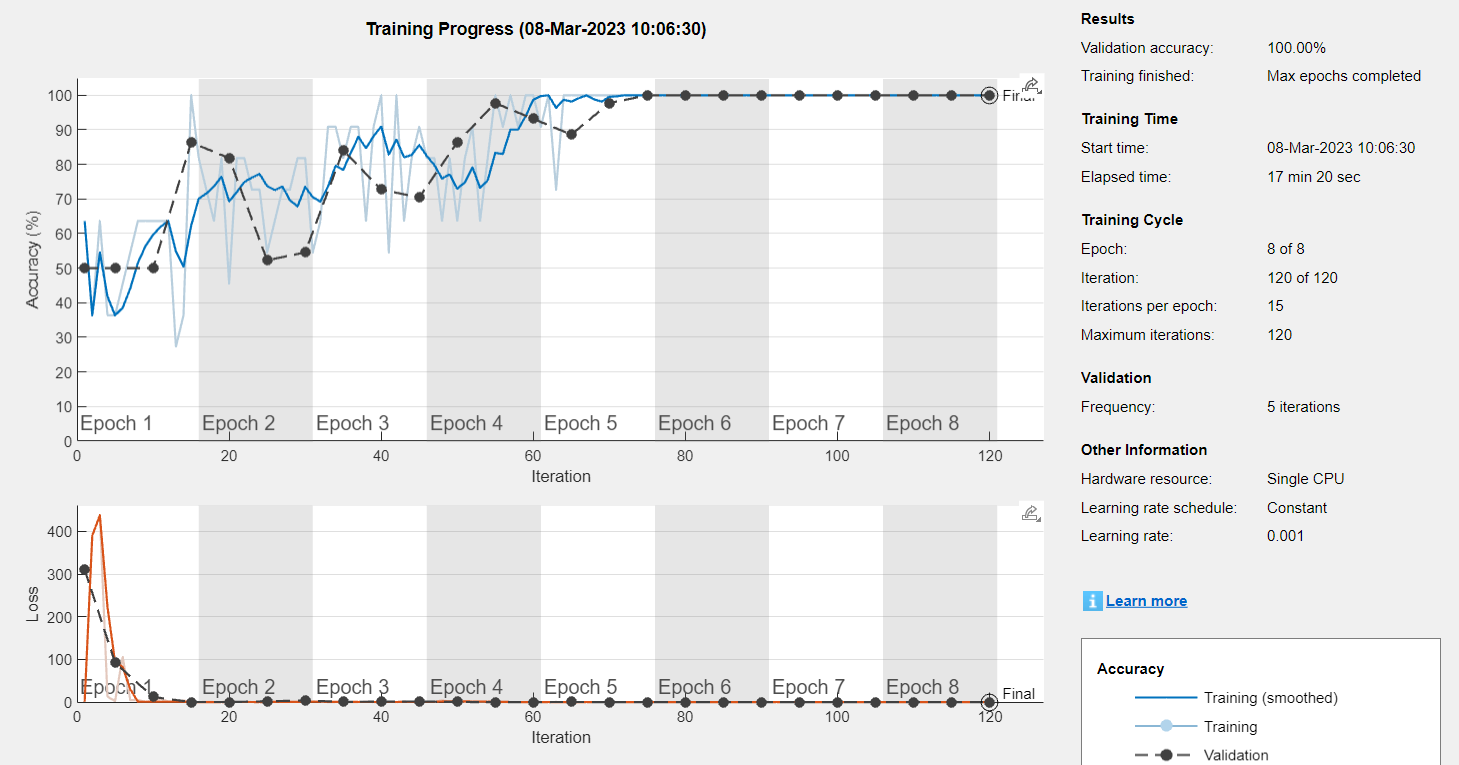

After training and saving our model, we can load it and check its performance to new data:

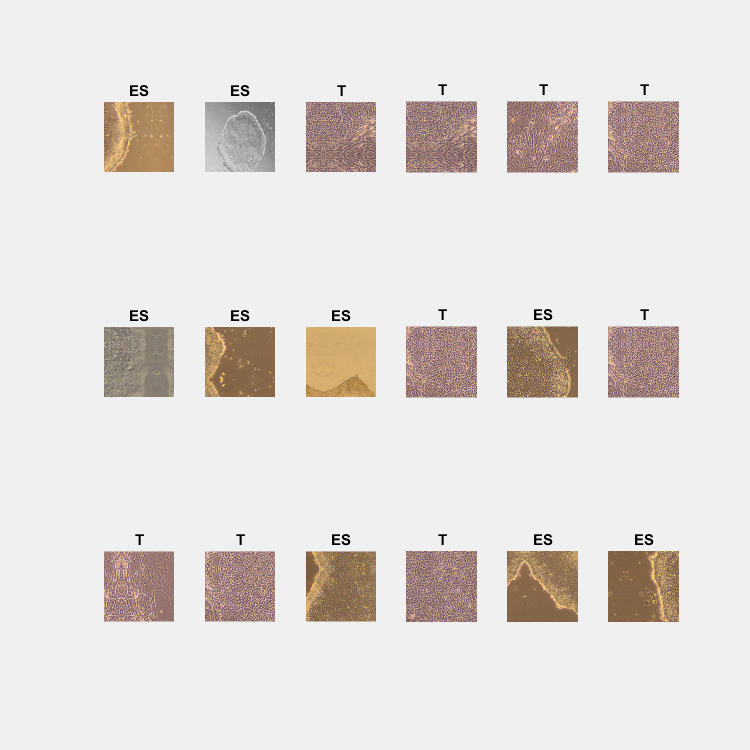

load("VGG16_trained.mat")

figure(),
allclass=[];
images_analyzed = zeros(1,18);
for i=1:18
    idx = randi(numel(testdata1.Files)); % generate a random index
    images_analyzed(i) = idx;
    I=readimage(testdata1,idx);
    class=classify(VGG16_trained,I);
    allclass=[allclass class];
    figure(2),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted2=allclass;

Let's generate a confucion matrix

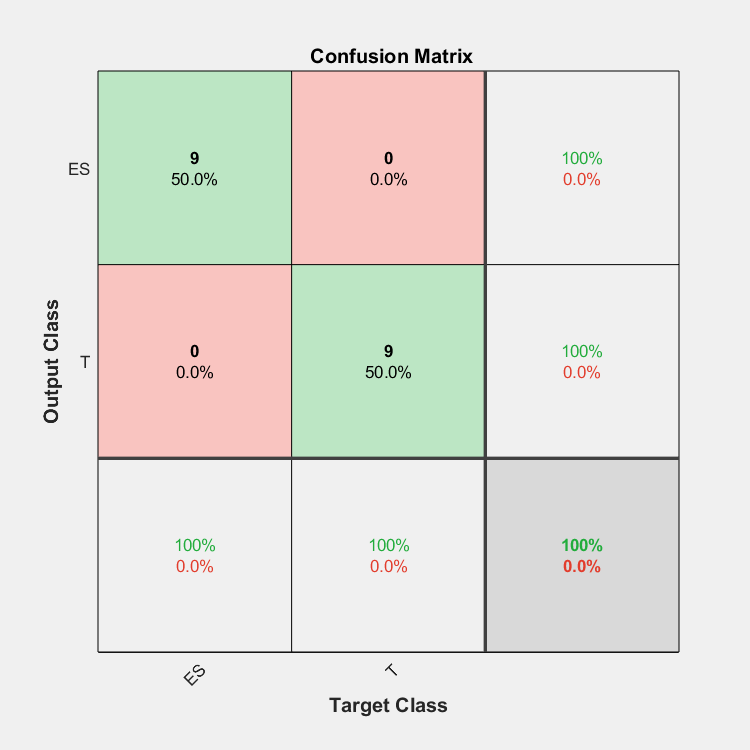

matrix2 =   Figure (PLOTCONFUSION2) with properties:

      Number: 13
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


figure(),
% Do not forget that at least one of the matrix must be transposed to generate a proper answer
matrix2 = plotconfusion(testdata2.Labels(images_analyzed),Predicted2')

Now let's measure its accuracy:

accuracy2 =mean(Predicted2==(testdata1.Labels(images_analyzed))')

accuracy2 = 1

## VGG19

In order to adjust this model for our application, the pre-trained neural network was opened in the Deep Learning Tool and  two layers were adjusted:

% deepNetworkDesigner(net3)

After that the model was trained with the set of images from Batch 1 and here is its performance:

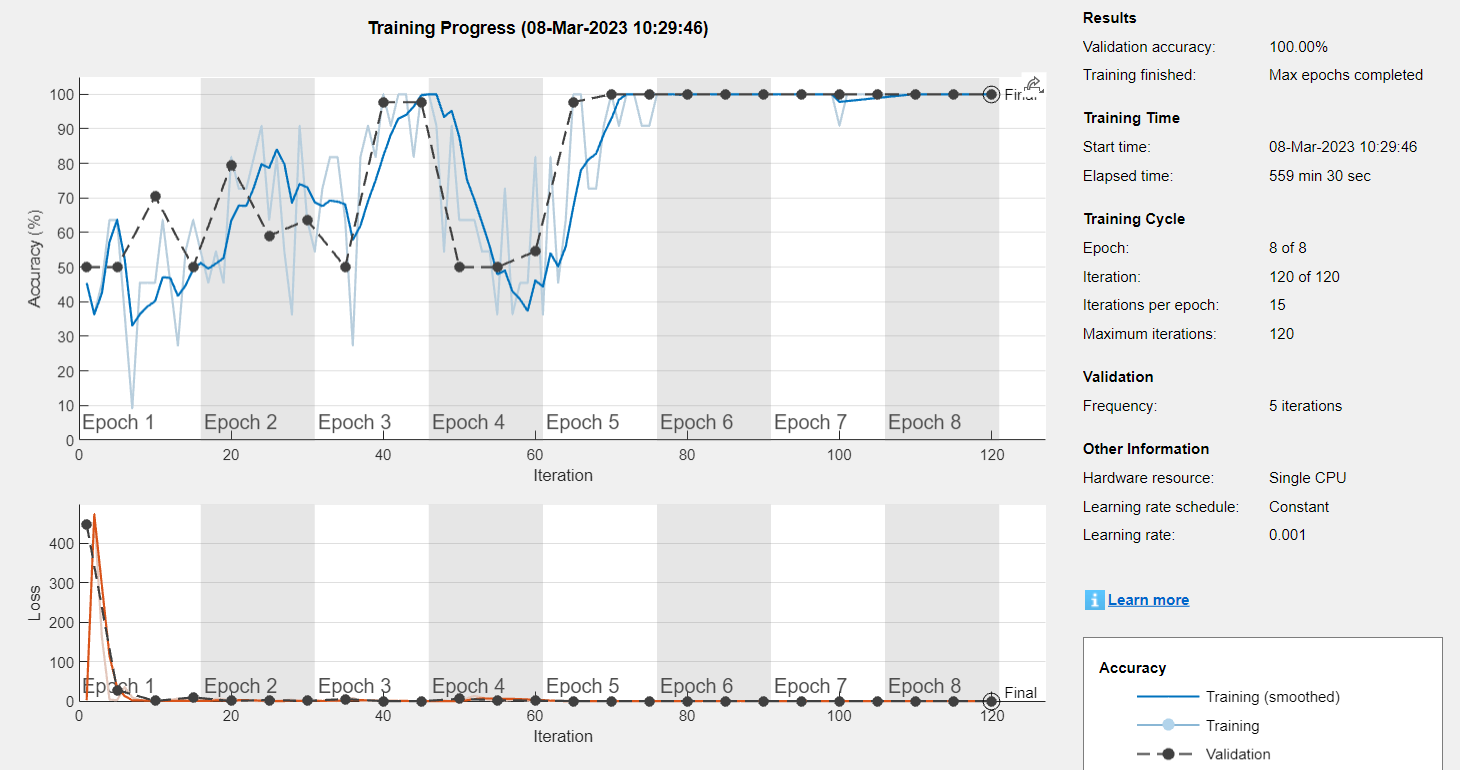

After training and saving our model, we can load it and check its performance to new data:

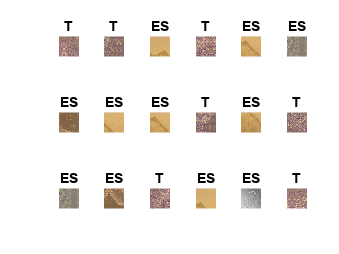

load("VGG19_trained.mat")

figure(),
allclass=[];
images_analyzed = zeros(1,18);
for i=1:18
    idx = randi(numel(testdata1.Files)); % generate a random index
    images_analyzed(i) = idx;
    I=readimage(testdata1,idx);
    class=classify(VGG19_trained,I);
    allclass=[allclass class];
    figure(3),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted3=allclass;

Let's generate a confucion matrix

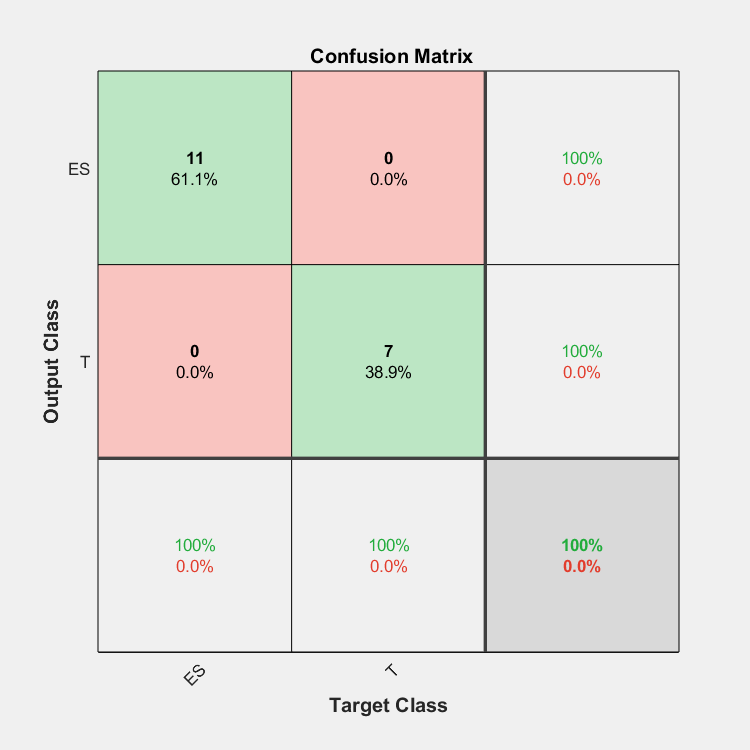

matrix3 =   Figure (PLOTCONFUSION3) with properties:

      Number: 15
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


figure(),
% Do not forget that at least one of the matrix must be transposed to generate a proper answer
matrix3 = plotconfusion(testdata1.Labels(images_analyzed),Predicted3')

Now let's measure its accuracy:

accuracy3 =mean(Predicted3==(testdata1.Labels(images_analyzed))')

accuracy3 = 1

## InceptionV3

In order to adjust this model for our application, the pre-trained neural network was opened in the Deep Learning Tool and  two layers were adjusted:

% deepNetworkDesigner(net4)

After that the model was trained with the set of images from Batch 1 and here is its performance:

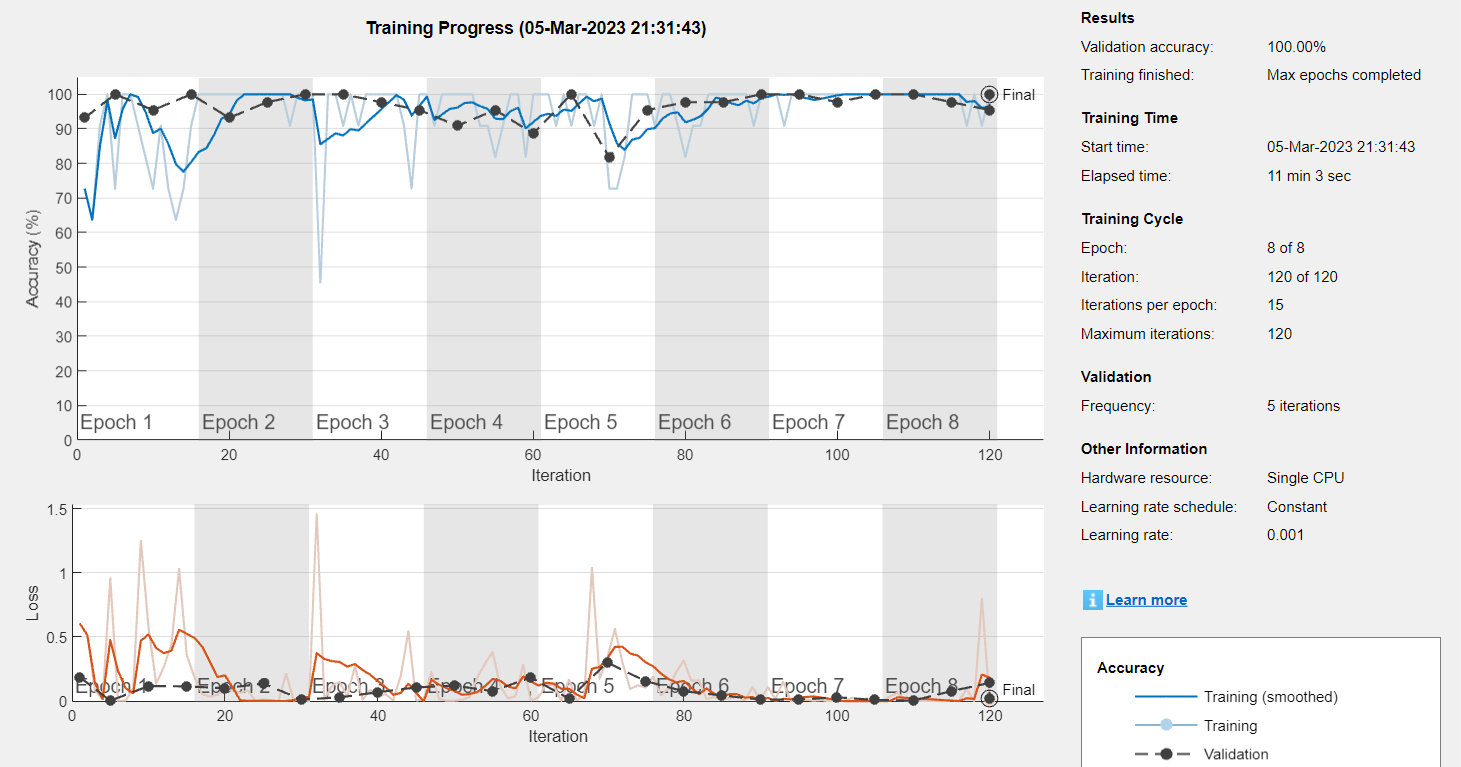

After training and saving our model, we can load it and check its performance to new data:

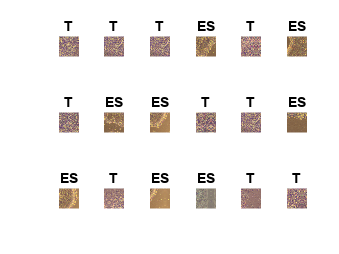

load("InceptionV3_trained.mat")

figure(),
allclass=[];
images_analyzed = zeros(1,18);
for i=1:18
    idx = randi(numel(testdata2.Files)); % generate a random index
    images_analyzed(i) = idx;
    I=readimage(testdata2,idx);
    class=classify(InceptionV3_trained,I);
    allclass=[allclass class];
    figure(4),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted4=allclass;

Let's generate a confucion matrix

matrix4 =   Figure (PLOTCONFUSION4) with properties:

      Number: 18
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


figure(),
% Do not forget that at least one of the matrix must be transposed to generate a proper answer
matrix4 = plotconfusion(testdata2.Labels(images_analyzed),Predicted4')

Now let's measure its accuracy:

accuracy4 =mean(Predicted4==(testdata2.Labels(images_analyzed))')

accuracy4 = 1

## Xception

In order to adjust this model for our application, the pre-trained neural network was opened in the Deep Learning Tool and  two layers were adjusted:

% deepNetworkDesigner(net5)

After that the model was trained with the set of images from Batch 1 and here is its performance:

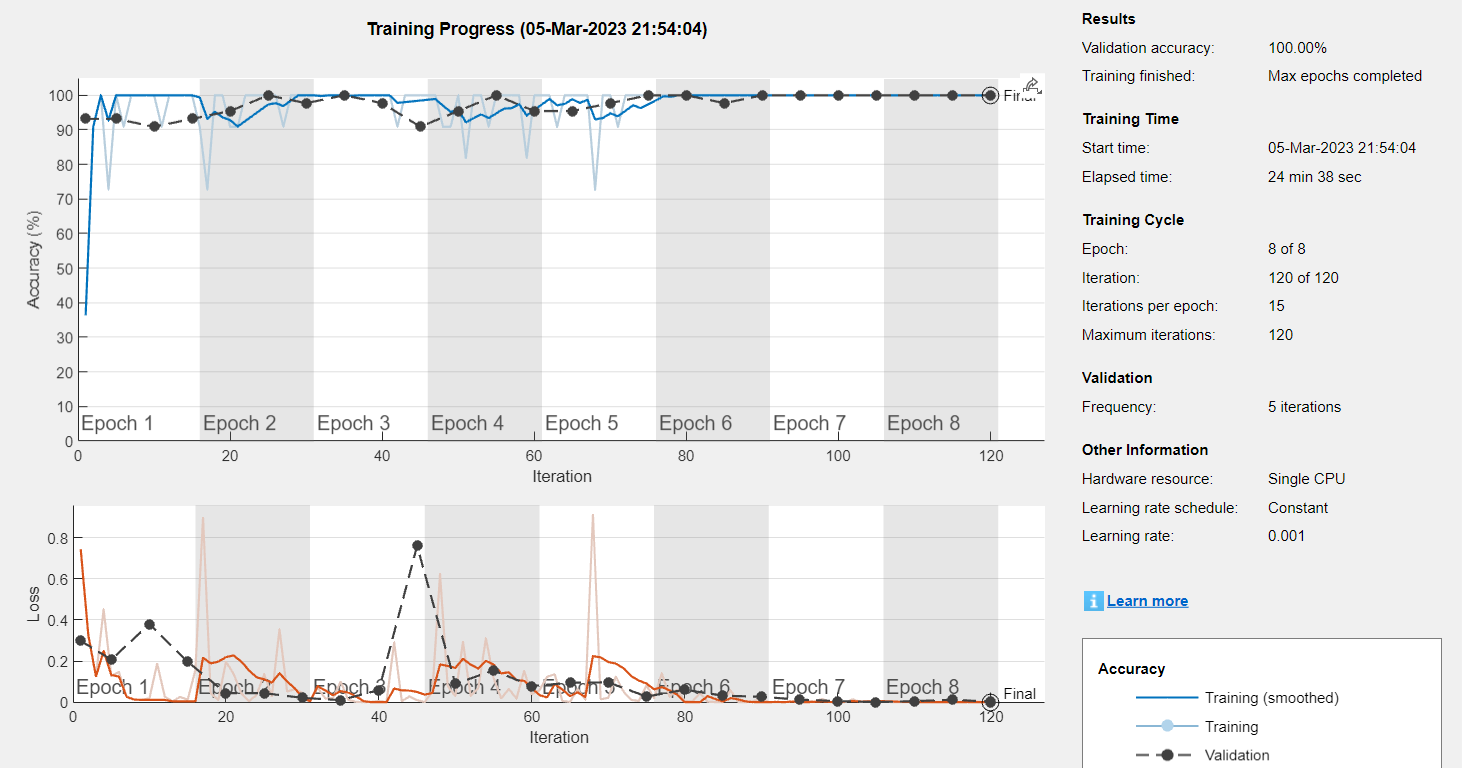

After training and saving our model, we can load it and check its performance to new data:

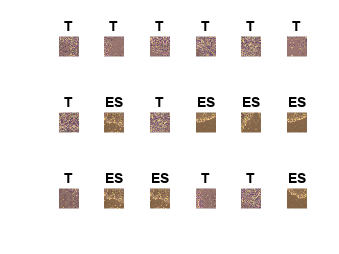

load("Xception_trained.mat")

figure(),
allclass=[];
images_analyzed = zeros(1,18);
for i=1:18
    idx = randi(numel(testdata2.Files)); % generate a random index
    images_analyzed(i) = idx;
    I=readimage(testdata2,idx);
    class=classify(Xception_trained,I);
    allclass=[allclass class];
    figure(5),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted5=allclass;

Let's generate a confucion matrix

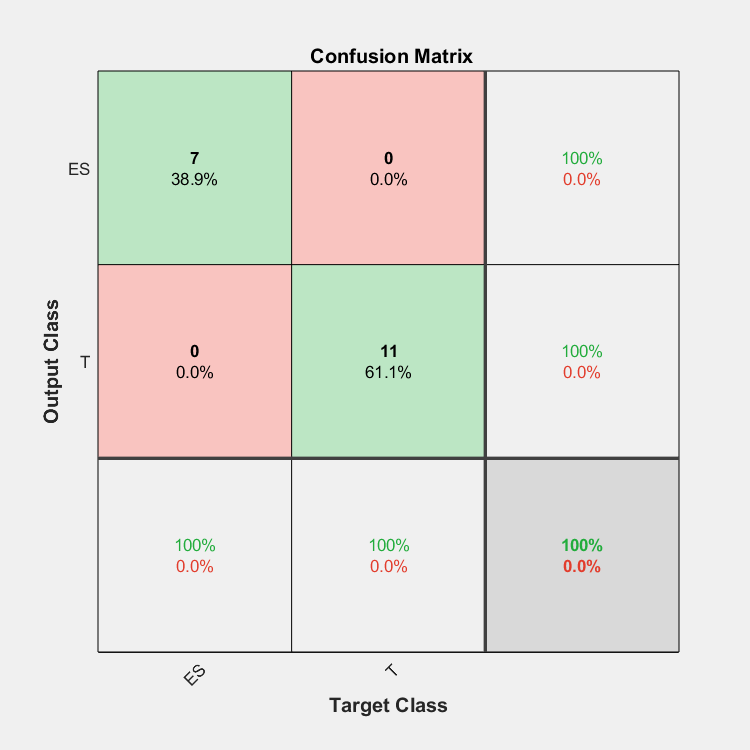

matrix5 =   Figure (PLOTCONFUSION5) with properties:

      Number: 20
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


figure(),
% Do not forget that at least one of the matrix must be transposed to generate a proper answer
matrix5 = plotconfusion(testdata2.Labels(images_analyzed),Predicted5')

Now let's measure its accuracy:

accuracy5 =mean(Predicted5==(testdata2.Labels(images_analyzed))')

accuracy5 = 1

# Results

## Testing our trained models with my images

Now that we have five different models trained to be able to differentiate trophoblasts and stem cells, we are gonna try to use this mode on my samples, i.e, images that I collected on my microscope. 

It is important to note that I do not work with trophoblasts, so unfortunately I do not have any cell images from this group. Therefore, we will only be evaluating the efficacy of determining stem cells (ES). However, I will deliberately include some "complex" images to test the models, where we have populations of differentiated and undifferentiated cells:

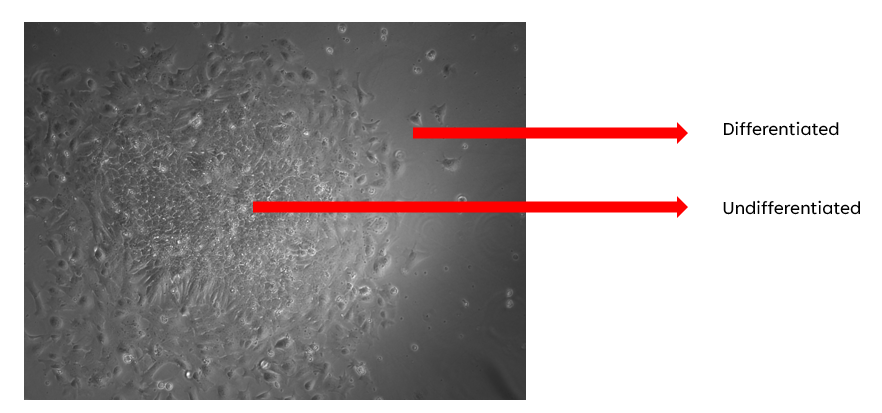

To utilize the images in my analysis, I first converted the original grayscale images into RGB format. After this, I resized the images to the desired dimensions using the "Image Batch Processor" tool, which implemented the custom functions created earlier in the workflow (image_proc_batch1.m and image_proc_batch2.m).

my_cells_path = 'C:\Users\victo\Downloads\Machine Learning Course\Project\my_hiPSC';

% Let's import our data collections
my_cells_batch1 = fullfile(my_cells_path,'batch1');
my_cells_batch2 = fullfile(my_cells_path,'batch2');

my_cells_1=imageDatastore(my_cells_batch1);
my_cells_2=imageDatastore(my_cells_batch2);

Now that we resized our images, we are good to use them into our models:

DenseNet

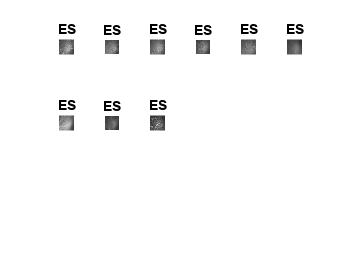

figure(),
allclass=[];
for i=1:9
    I=readimage(my_cells_1,i);
    class=classify(DenseNet_trained,I);
    allclass=[allclass class];
    figure(6),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted_densenet=allclass;

VGG16

figure(),
allclass=[];
for i=1:9
    I=readimage(my_cells_1,i);
    class=classify(VGG16_trained,I);
    allclass=[allclass class];
    figure(7),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted_vgg16=allclass;

VGG19

figure(),
allclass=[];
for i=1:9
    I=readimage(my_cells_1,i);
    class=classify(VGG19_trained,I);
    allclass=[allclass class];
    figure(8),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted_vgg19=allclass;

InceptionV3

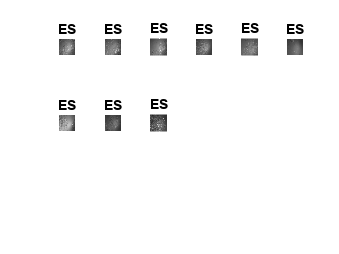

figure(),
allclass=[];
for i=1:9
    I=readimage(my_cells_2,i);
    class=classify(InceptionV3_trained,I);
    allclass=[allclass class];
    figure(9),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted_inceptionv3=allclass;

Xception

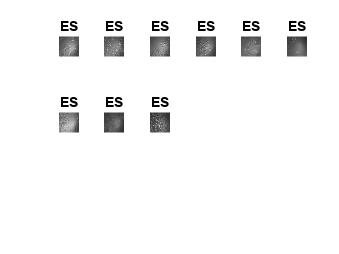

figure(),
allclass=[];
for i=1:9
    I=readimage(my_cells_2,i);
    class=classify(Xception_trained,I);
    allclass=[allclass class];
    figure(10),
    subplot(3,6,i)
    imshow(I)
    title(char(class))
end

Predicted_xception=allclass;

The results of our analysis demonstrate that all of the models were successful in accurately classifying the images into stem cells, despite variations in image acquisition conditions such as microscope type, lens, resolution, and origin. This indicates that our model was able to effectively capture and utilize the relevant features of the cell populations, showcasing the robustness and generalizability of our approach.

# Conclusion

In conclusion, the trained models, including DenseNet, VGG16, VGG19, InceptionV3, and Xception, worked with high efficiency for the images provided by the authors of the article and for the images collected in the laboratory. The models were able to correctly classify the stem cells images under different conditions, such as microscope, lens, resolution, and origin. Although the models were not trained with as many images as the authors used, the results were still promising, which suggests that these models have the potential to be used in the field of stem cell research. However, it is important to note that due to the computer capacity limitation, only 100 images for each condition were used, which is significantly less than the 1500 images the authors trained. 

In additional, for the original work pre-trained models were used and here we were able to demonstrate some of the adavantegs of using them over building a model from scratch. One of the main advantages is that pre-trained models have already learned features on large and diverse datasets, making them capable of performing well on various image recognition tasks. This saves a significant amount of time and computational resources that would have been spent on training a model from scratch. Additionally, pre-trained models often have a large number of parameters, which makes them capable of recognizing more complex features than models with fewer parameters. Another advantage is that pre-trained models are often easily accessible, meaning that researchers without extensive knowledge of deep learning can still take advantage of state-of-the-art models. Finally, using pre-trained models reduces the risk of overfitting, as the models have already learned to generalize well to new images. Overall, using pre-trained models such as DenseNet, VGG16, VGG19, InceptionV3, and Xception can significantly speed up the training process and improve the accuracy of image recognition tasks.

The results of our classification models indicate that they were able to accurately classify the images into the stem cell population. This is a promising outcome that suggests our models have effectively captured the unique features of these cell populations. By accurately identifying stem cells from other cell types, these models could be useful for various applications in the field of cell biology, such as identifying potential new therapies or studying the process of cell differentiation. However, it's important to note that further testing and validation would be necessary to fully assess the effectiveness and potential limitations of these models.

This project has been a fascinating journey of exploring and manipulating popular deep learning models like DenseNet, VGG16, VGG19, InceptionV3, and Xception, using them to classify different types of cell images. By using pre-trained models, I was able to save a considerable amount of time and computational resources that would have been required to train a model from scratch. The image batch processor tool was a valuable asset in helping me pre-process and manipulate the large datasets used in this project. Overall, this project provided me with an excellent opportunity to enhance my knowledge of deep learning models and how to adapt them to my specific needs while working with real-world datasets.

# Reference

Liu Y, Zhang Y, Cui J. Recognized trophoblast-like cells conversion from human embryonic stem cells by BMP4 based on convolutional neural network. Reprod Toxicol. 2021 Jan;99:39-47. doi: 10.1016/j.reprotox.2020.11.006. Epub 2020 Nov 26. PMID: 33249234.